filenames = dir('*.mat');
for k = 1:length(filenames)
    data{k}=load(filenames(k).name);
    x{k}=data{k}.data_to_save(:,1);
    CH1{k}=data{k}.data_to_save(:,2);
    DIFF{k}=data{k}.data_to_save(:,3);
    REF{k}=data{k}.data_to_save(:,4);
end


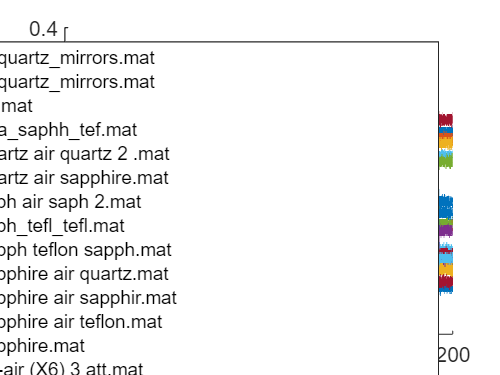

%plkottign difference
figure
legend_entries={};
for k = 1:length(filenames)
    hold on
    plot(x{k},DIFF{k});
    legend_entries{k} = filenames(k).name;  
end
hold off
legend(legend_entries,'interpreter','none');  

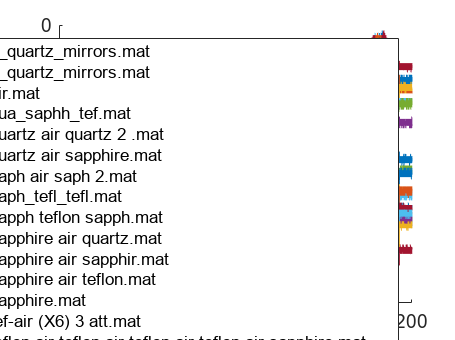


%plotting raw data
figure
legend_entries={};
for k = 1:length(filenames)
    hold on
    plot(x{k},CH1{k});
    legend_entries{k} = filenames(k).name;  
end
hold off
legend(legend_entries,'interpreter','none');  

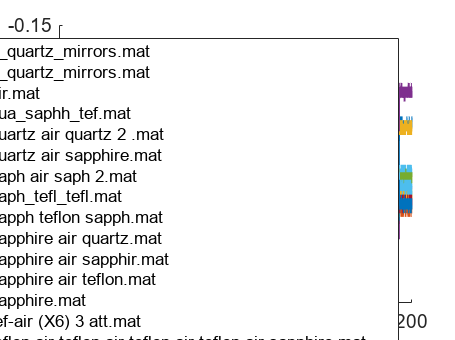


%plotting references
figure
legend_entries={};
for k = 1:length(filenames)
    hold on
    plot(x{k},REF{k});
    legend_entries{k} = filenames(k).name;  
end
hold off
legend(legend_entries,'interpreter','none');  